% load variables in workspace of LAB0 (parameters according to motor 8)
load params_inertial_case.mat
load params_estimated_LAB0.mat
load PID_params_LAB0.mat

% open simulink model (we added the antiwindup component)
open_system('robust_tracking_integral_BONUS.slx');
set_param('robust_tracking_integral_BONUS','SolverType', 'Variable-step', 'Solver', 'ode45', 'StopTime', '5');

Beq = Beq_hat;                           % mot.B + mld.B/gbox.N^2;    
Jeq = Jeq_hat;
model.km = (drv.dcgain*mot.Kt)/(Req*Beq + mot.Kt*mot.Ke);
model.Tm = (Req*Jeq)/(Req*Beq + mot.Kt*mot.Ke);
sens.enc.pulse2deg = 360/2000; % in lab da cambiare in 360/4096

%   non-encapsulated SS data
A = [0, 1; 0, -1/model.Tm];
B = [0; model.km/(gbox.N*model.Tm)];
C = [1, 0];
D = 0;

%   SS data encapulated in a SS object
sys = ss(A, B, C, D);

%compute N_x, N_u
S = [A,B;C,0];
b=[0 0 1]';
N = linsolve(S,b); %Sx=b
N_x = [N(1) N(2)];
N_u = N(3);

% define H1 filter
H1.wc = 2*pi*50;   
H1.d = 1/sqrt(2);
H1s = tf([H1.wc^2,0],[1, 2*H1.d*H1.wc, H1.wc^2]);
[numH1, denH1] = tfdata(H1s,'v');

%specs
spec.ts5    = 0.15;         % Settling-time
spec.Mp     = 0.1;          % Overshoot
spec.damp   = log(1/spec.Mp) / (sqrt(pi^2+(log(1/spec.Mp))^2));
spec.wn   = 3 / (spec.damp*spec.ts5);

% define speed filter
fltr.wc = 2*pi*20;            % was 2*pi*50
Hws = tf([fltr.wc^2,0],[1, 2*fltr.d*fltr.wc, fltr.wc^2]);
[numHws, denHws] = tfdata(Hws,'v');

step_size = 70; 
awu.Kw = [5,10,20,5/ctrl.ts5]

awu = struct with fields:
    Kw: [5 10 20 33.3333]


## Robust Tracking Design

%poles
sigma=-spec.damp*spec.wn;
omega_d=spec.wn*sqrt(1-spec.damp^2);

p1 = [sigma+omega_d*j , sigma-omega_d*j , sigma ];
p2 = [sigma , sigma , sigma ];
p3 = [2*sigma+omega_d*j , 2*sigma-omega_d*j , 2*sigma ];
p4 = [2*sigma+omega_d*j , 2*sigma-omega_d*j , 3*sigma ];

%space model with augmented state
zer = zeros(2,1);
Ae=[0 C; zer A];
Be=[0; B];
Ce=[0 C];

%1st pole
ctrl.Kw = awu.Kw(4);
Ke = acker(Ae,Be,p1);
sim('robust_tracking_integral_BONUS');
data.tr1    = MotorData.time;
data.thlr1  = MotorData.signals(1).values;

%2nd pole
ctrl.Kw = awu.Kw(4);
Ke = acker(Ae,Be,p2);
sim('robust_tracking_integral_BONUS');
data.tr2    = MotorData.time;
data.thlr2  = MotorData.signals(1).values;

%3rd pole
ctrl.Kw = awu.Kw(4);
Ke = acker(Ae,Be,p3);
sim('robust_tracking_integral_BONUS');
data.tr3    = MotorData.time;
data.thlr3  = MotorData.signals(1).values;

%4th pole
ctrl.Kw = awu.Kw(4);
Ke = acker(Ae,Be,p4);
sim('robust_tracking_integral_BONUS');
data.tr4    = MotorData.time;
data.thlr4  = MotorData.signals(1).values;

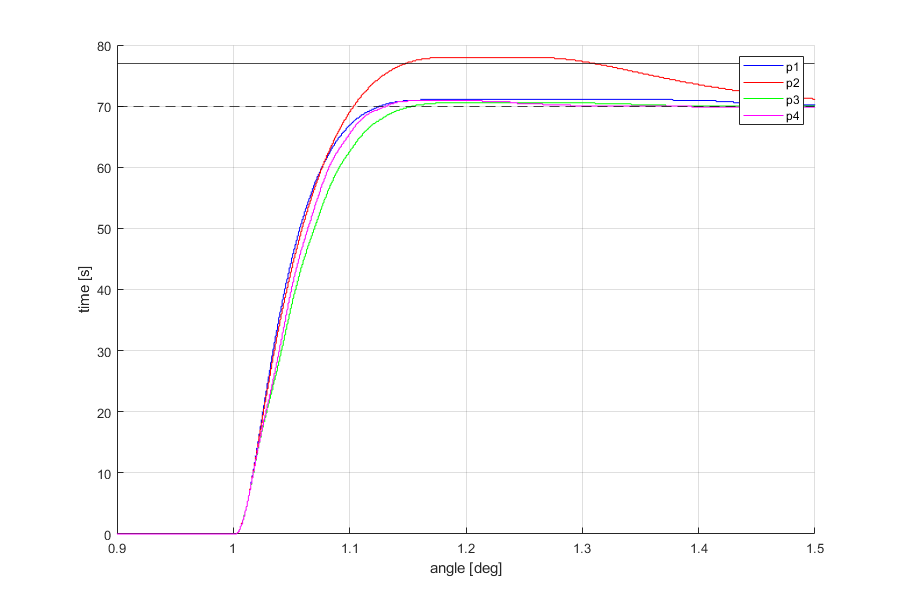

figure('Renderer', 'painters', 'Position', [10 10 900 600])
hold on;
plot(data.tr1,data.thlr1,'b');
plot(data.tr2,data.thlr2,'r');
plot(data.tr3,data.thlr3,'g');
plot(data.tr4,data.thlr4,'m');
yline(step_size*1.1,'k')
yline(step_size,'k--')
hold off;
legend('p1','p2','p3','p4');
xlabel('angle [deg]');
ylabel('time [s]');
grid on
xlim([0.9,1.5]);

**P2 don't works well **

p1:

awu.Kw = [0.7,1,2, 3]

awu = struct with fields:
    Kw: [0.7000 1 2 3]


Ke = acker(Ae,Be,p1);
ctrl.Kw = awu.Kw(1);
sim('robust_tracking_integral_BONUS');
data.p1.t1   = MotorData.time;
data.p1.th1  = MotorData.signals(1).values;
ctrl.Kw = awu.Kw(2);
sim('robust_tracking_integral_BONUS');
data.p1.t2   = MotorData.time;
data.p1.th2  = MotorData.signals(1).values;
ctrl.Kw = awu.Kw(3);
sim('robust_tracking_integral_BONUS');
data.p1.t3   = MotorData.time;
data.p1.th3  = MotorData.signals(1).values;
ctrl.Kw = awu.Kw(4);
sim('robust_tracking_integral_BONUS');
data.p1.t4   = MotorData.time;
data.p1.th4  = MotorData.signals(1).values;

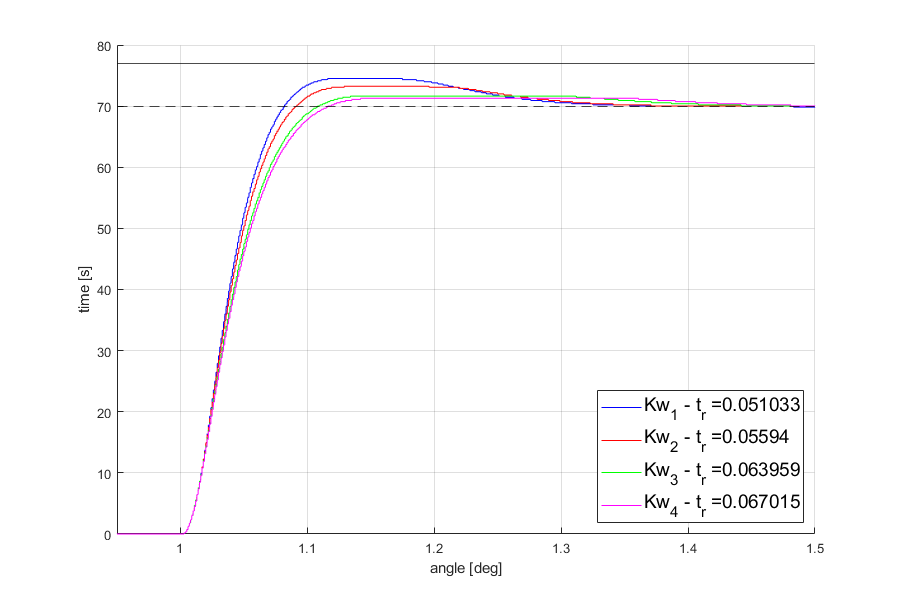

resp.p1.k1 = stepinfo(data.p1.th1,data.p1.t1,"SettlingTimeThreshold",0.05);
resp.p1.k2 = stepinfo(data.p1.th2,data.p1.t2,"SettlingTimeThreshold",0.05);
resp.p1.k3 = stepinfo(data.p1.th3,data.p1.t3,"SettlingTimeThreshold",0.05);
resp.p1.k4 = stepinfo(data.p1.th4,data.p1.t4,"SettlingTimeThreshold",0.05);

figure('Renderer', 'painters', 'Position', [10 10 900 600])
hold on;
plot(data.p1.t1,data.p1.th1,'b');
plot(data.p1.t2,data.p1.th2,'r');
plot(data.p1.t3,data.p1.th3,'g');
plot(data.p1.t4,data.p1.th4,'m');
yline(step_size,'k--')
yline(step_size*1.1,'k')
hold off;
legend(['Kw_1 - t_r =' num2str(resp.p1.k1.RiseTime)], ...
    ['Kw_2 - t_r =' num2str(resp.p1.k2.RiseTime)], ...
    ['Kw_3 - t_r =' num2str(resp.p1.k3.RiseTime)], ...
    ['Kw_4 - t_r =' num2str(resp.p1.k4.RiseTime)],'Location','southeast','FontSize',14);
xlabel('angle [deg]');
ylabel('time [s]');
grid on
xlim([0.95,1.5]);

p3:

awu.Kw = [0.05,0.1,0.5, 1]

awu = struct with fields:
    Kw: [0.0500 0.1000 0.5000 1]


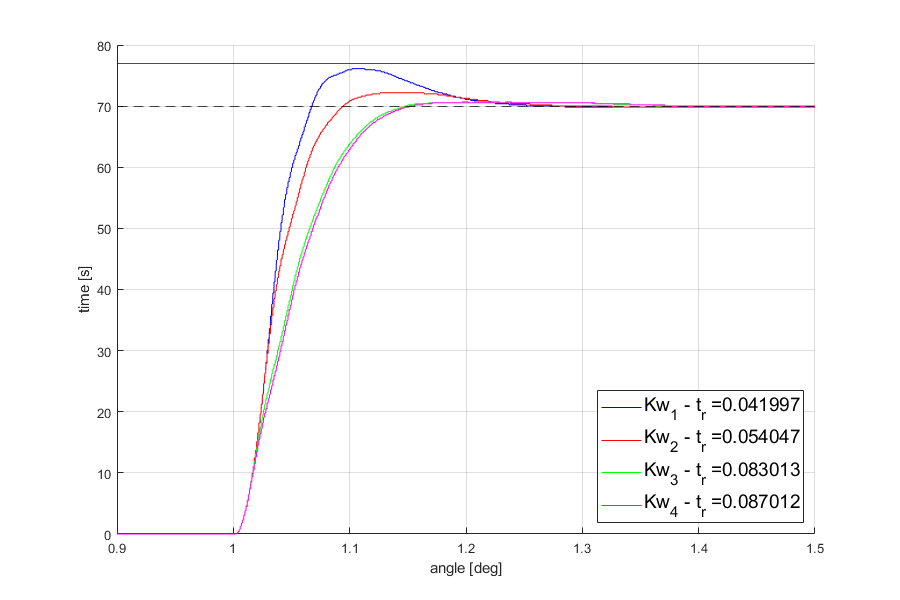

Ke = acker(Ae,Be,p3);
ctrl.Kw = awu.Kw(1);
sim('robust_tracking_integral_BONUS');
data.p3.t1   = MotorData.time;
data.p3.th1  = MotorData.signals(1).values;
ctrl.Kw = awu.Kw(2);
sim('robust_tracking_integral_BONUS');
data.p3.t2   = MotorData.time;
data.p3.th2  = MotorData.signals(1).values;
ctrl.Kw = awu.Kw(3);
sim('robust_tracking_integral_BONUS');
data.p3.t3   = MotorData.time;
data.p3.th3  = MotorData.signals(1).values;
ctrl.Kw = awu.Kw(4);
sim('robust_tracking_integral_BONUS');
data.p3.t4   = MotorData.time;
data.p3.th4  = MotorData.signals(1).values;

resp.p3.k1 = stepinfo(data.p3.th1,data.p3.t1,"SettlingTimeThreshold",0.05);
resp.p3.k2 = stepinfo(data.p3.th2,data.p3.t2,"SettlingTimeThreshold",0.05);
resp.p3.k3 = stepinfo(data.p3.th3,data.p3.t3,"SettlingTimeThreshold",0.05);
resp.p3.k4 = stepinfo(data.p3.th4,data.p3.t4,"SettlingTimeThreshold",0.05);

figure('Renderer', 'painters', 'Position', [10 10 900 600])
hold on;
plot(data.p3.t1,data.p3.th1,'b');
plot(data.p3.t2,data.p3.th2,'r');
plot(data.p3.t3,data.p3.th3,'g');
plot(data.p3.t4,data.p3.th4,'m');
yline(step_size,'k--')
yline(step_size*1.1,'k')
hold off;
legend(['Kw_1 - t_r =' num2str(resp.p3.k1.RiseTime)], ...
    ['Kw_2 - t_r =' num2str(resp.p3.k2.RiseTime)], ...
    ['Kw_3 - t_r =' num2str(resp.p3.k3.RiseTime)], ...
    ['Kw_4 - t_r =' num2str(resp.p3.k4.RiseTime)],'Location','southeast','FontSize',14);
xlabel('angle [deg]');
ylabel('time [s]');
grid on
xlim([0.9,1.5]);

p4:

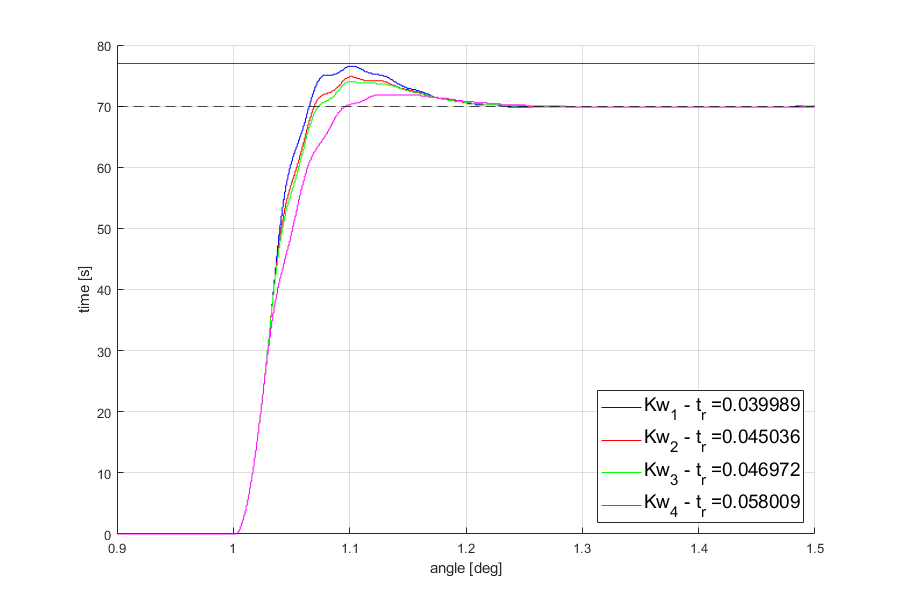

awu.Kw = [0.035,0.045,0.05, 0.09];
Ke = acker(Ae,Be,p4);
ctrl.Kw = awu.Kw(1);
sim('robust_tracking_integral_BONUS');
data.p4.t1   = MotorData.time;
data.p4.th1  = MotorData.signals(1).values;
ctrl.Kw = awu.Kw(2);
sim('robust_tracking_integral_BONUS');
data.p4.t2   = MotorData.time;
data.p4.th2  = MotorData.signals(1).values;
ctrl.Kw = awu.Kw(3);
sim('robust_tracking_integral_BONUS');
data.p4.t3   = MotorData.time;
data.p4.th3  = MotorData.signals(1).values;
ctrl.Kw = awu.Kw(4);
sim('robust_tracking_integral_BONUS');
data.p4.t4   = MotorData.time;
data.p4.th4  = MotorData.signals(1).values;

resp.p4.k1 = stepinfo(data.p4.th1,data.p4.t1,"SettlingTimeThreshold",0.05);
resp.p4.k2 = stepinfo(data.p4.th2,data.p4.t2,"SettlingTimeThreshold",0.05);
resp.p4.k3 = stepinfo(data.p4.th3,data.p4.t3,"SettlingTimeThreshold",0.05);
resp.p4.k4 = stepinfo(data.p4.th4,data.p4.t4,"SettlingTimeThreshold",0.05);

figure('Renderer', 'painters', 'Position', [10 10 900 600])
hold on;
plot(data.p4.t1,data.p4.th1,'b');
plot(data.p4.t2,data.p4.th2,'r');
plot(data.p4.t3,data.p4.th3,'g');
plot(data.p4.t4,data.p4.th4,'m');
yline(step_size,'k--')
yline(step_size*1.1,'k')
hold off;
legend(['Kw_1 - t_r =' num2str(resp.p4.k1.RiseTime)], ...
    ['Kw_2 - t_r =' num2str(resp.p4.k2.RiseTime)], ...
    ['Kw_3 - t_r =' num2str(resp.p4.k3.RiseTime)], ...
    ['Kw_4 - t_r =' num2str(resp.p4.k4.RiseTime)],'Location','southeast','FontSize',14);
xlabel('angle [deg]');
ylabel('time [s]');
grid on
xlim([0.9,1.5]);

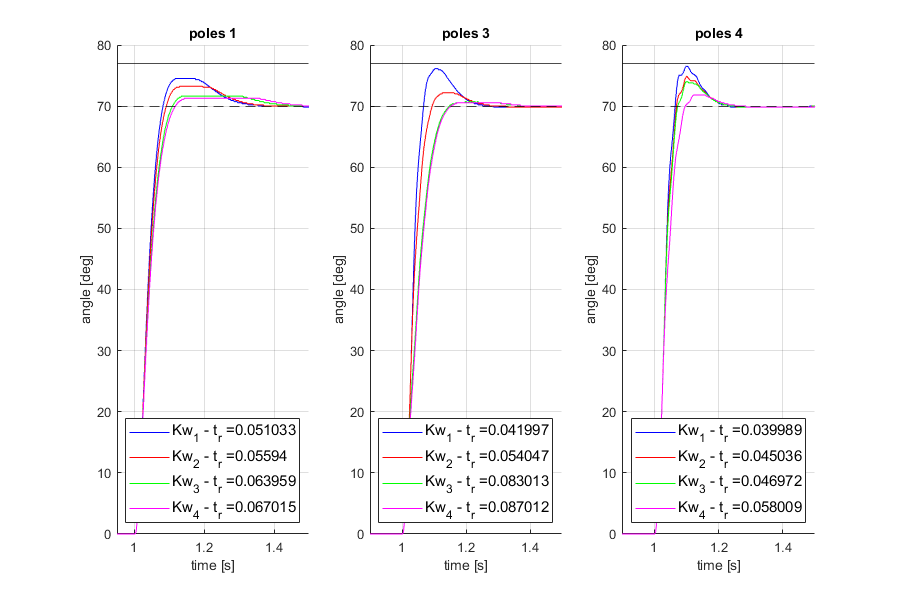

figure('Renderer', 'painters', 'Position', [10 10 900 600])

subplot(1,3,1);
title('poles 1');
hold on;
plot(data.p1.t1,data.p1.th1,'b');
plot(data.p1.t2,data.p1.th2,'r');
plot(data.p1.t3,data.p1.th3,'g');
plot(data.p1.t4,data.p1.th4,'m');
yline(step_size,'k--')
yline(step_size*1.1,'k')
hold off;
legend(['Kw_1 - t_r =' num2str(resp.p1.k1.RiseTime)], ...
    ['Kw_2 - t_r =' num2str(resp.p1.k2.RiseTime)], ...
    ['Kw_3 - t_r =' num2str(resp.p1.k3.RiseTime)], ...
    ['Kw_4 - t_r =' num2str(resp.p1.k4.RiseTime)],'Location','southeast','FontSize',11);
ylabel('angle [deg]');
xlabel('time [s]');
grid on
xlim([0.95,1.5]);
subplot(1,3,2);
title('poles 3');
hold on;
plot(data.p3.t1,data.p3.th1,'b');
plot(data.p3.t2,data.p3.th2,'r');
plot(data.p3.t3,data.p3.th3,'g');
plot(data.p3.t4,data.p3.th4,'m');
yline(step_size,'k--')
yline(step_size*1.1,'k')
hold off;
legend(['Kw_1 - t_r =' num2str(resp.p3.k1.RiseTime)], ...
    ['Kw_2 - t_r =' num2str(resp.p3.k2.RiseTime)], ...
    ['Kw_3 - t_r =' num2str(resp.p3.k3.RiseTime)], ...
    ['Kw_4 - t_r =' num2str(resp.p3.k4.RiseTime)],'Location','southeast','FontSize',11);
ylabel('angle [deg]');
xlabel('time [s]');
grid on
xlim([0.9,1.5]);
subplot(1,3,3);
title('poles 4');
hold on;
plot(data.p4.t1,data.p4.th1,'b');
plot(data.p4.t2,data.p4.th2,'r');
plot(data.p4.t3,data.p4.th3,'g');
plot(data.p4.t4,data.p4.th4,'m');
yline(step_size,'k--')
yline(step_size*1.1,'k')
hold off;
legend(['Kw_1 - t_r =' num2str(resp.p4.k1.RiseTime)], ...
    ['Kw_2 - t_r =' num2str(resp.p4.k2.RiseTime)], ...
    ['Kw_3 - t_r =' num2str(resp.p4.k3.RiseTime)], ...
    ['Kw_4 - t_r =' num2str(resp.p4.k4.RiseTime)],'Location','southeast','FontSize',11);
ylabel('angle [deg]');
xlabel('time [s]');
grid on
xlim([0.9,1.5]);

## Robust tracking with the extended estimator approach

% open simulink model (we added the antiwindup component)
open_system('robust_tracking_extended_estimator_bonus');
set_param('robust_tracking_extended_estimator_bonus','SolverType', 'Variable-step', 'Solver', 'ode45', 'StopTime', '5');

% reference
step_size = 70; 

%"controller" eigenvalues and "estimator" eigenvalues
pc1=-spec.damp*spec.wn + j*spec.wn*sqrt(1-spec.damp^2);
pc2=-spec.damp*spec.wn - j*spec.wn*sqrt(1-spec.damp^2);
pc = [pc1 , pc2];

pe1=2*spec.wn*exp(j*(-pi+pi/3));
pe2 = conj(pe1);
pe3=2*spec.wn*exp(j*(-pi+pi/6));
pe4 = conj(pe3);
pe5=-2*spec.wn;
%1st choise
p1 =[pe1 pe2 pe5]; 
%2nd choise
p2 =[pe3 pe4 pe5];

% Define system
Ap = 0;
Cp = 1;
A = [0, 1; 0, -1/model.Tm];
B = [0; model.km/(gbox.N*model.Tm)];
C = [1, 0];
D = 0;
zer = zeros(1,2);
BCp = B*Cp;

Ae = [Ap , zer;
      BCp , A ];
Be = [0 ; B ];
Ce = [0 , C];
K3 = place(A,B,pc)

K3 =     8.6927    0.1139


Le1 = place(Ae.',Ce.',p1).';
Le2 = place(Ae.',Ce.',p2).';

Aest = Ae - Le1*Ce;
Best = [Be Le1];
Cest = eye(3);
Dest = zeros(3,2);

% with the extended estimator approach
%1st choise
sim('robust_tracking_extended_estimator_bonus');
data.test1    = MotorData.time;
data.thlest1  = MotorData.signals(1).values;

%2nd choise
Aest = Ae - Le2*Ce;
Best = [Be Le2];

sim('robust_tracking_extended_estimator_bonus');
data.test2    = MotorData.time;
data.thlest2  = MotorData.signals(1).values;


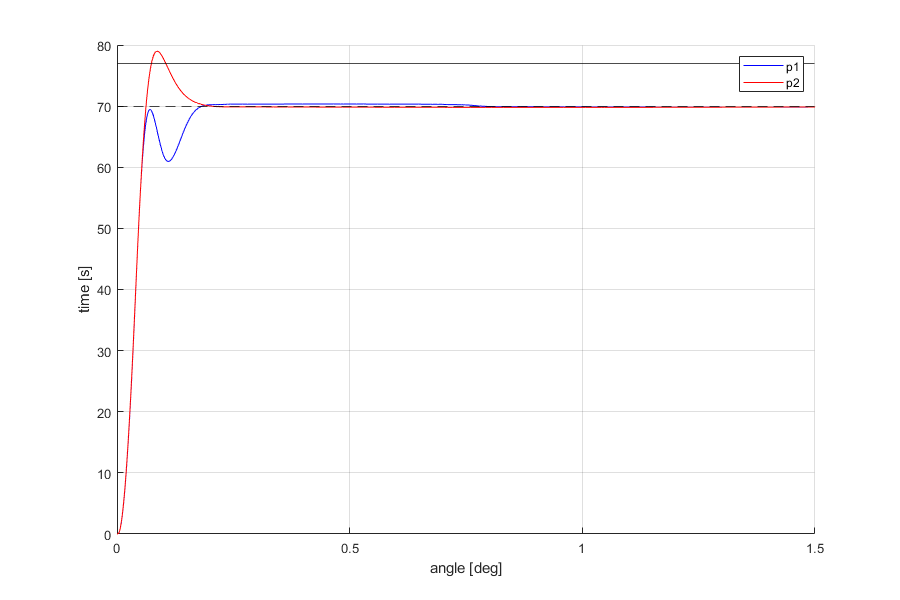

figure('Renderer', 'painters', 'Position', [10 10 900 600])
hold on;
plot(data.test1,data.thlest1,'b');
plot(data.test2,data.thlest2,'r');
% plot(data.test3,data.thlest3,'g');
% plot(data.test4,data.thlest4,'m');
yline(step_size*1.1,'k')
yline(step_size,'k--')
hold off;
legend('p1','p2');%,'p3','p4');
xlabel('angle [deg]');
ylabel('time [s]');
grid on
xlim([0,1.5]);

step_est1 = stepinfo(data.thlest1,data.test1,"SettlingTimeThreshold",0.05)

step_est1 = struct with fields:
        RiseTime: 0.0397
    SettlingTime: 0.1462
     SettlingMin: 60.9564
     SettlingMax: 70.3456
       Overshoot: 0.6313
      Undershoot: 0
            Peak: 70.3456
        PeakTime: 0.4706


step_est2 = stepinfo(data.thlest2,data.test2,"SettlingTimeThreshold",0.05)

step_est2 = struct with fields:
        RiseTime: 0.0391
    SettlingTime: 0.1292
     SettlingMin: 63.0047
     SettlingMax: 78.9806
       Overshoot: 13.0316
      Undershoot: 0
            Peak: 78.9806
        PeakTime: 0.0860


### Fusione 

% open simulink model (we added the antiwindup component)
open_system('robust_tracking_integral_estBONUS.slx');
set_param('robust_tracking_integral_estBONUS','SolverType', 'Variable-step', 'Solver', 'ode45', 'StopTime', '5');

% reference
step_size = 70; 

%"controller" eigenvalues and "estimator" eigenvalues
pc1=-spec.damp*spec.wn + j*spec.wn*sqrt(1-spec.damp^2);
pc2=-spec.damp*spec.wn - j*spec.wn*sqrt(1-spec.damp^2);
pc = [pc1 , pc2];

pe1=2*spec.wn*exp(j*(-pi+pi/3));
pe2 = conj(pe1);
pe3=2*spec.wn*exp(j*(-pi+pi/6));
pe4 = conj(pe3);
pe5=-2*spec.wn;
%1st choise
p1 =[pe1 pe2 pe5]; 
%2nd choise
p2 =[pe3 pe4 pe5];

% Define system
Ap = 0;
Cp = 1;
A = [0, 1; 0, -1/model.Tm];
B = [0; model.km/(gbox.N*model.Tm)];
C = [1, 0];
D = 0;
zer = zeros(1,2);
BCp = B*Cp;

Ae = [Ap , zer;
      BCp , A ];
Be = [0 ; B ];
Ce = [0 , C];
K3 = place(A,B,pc)

K3 =     8.6927    0.1139


Le1 = place(Ae.',Ce.',p1).';
Le2 = place(Ae.',Ce.',p2).';

Aest = Ae - Le1*Ce;
Best = [Be Le1];
Cest = eye(3);
Dest = zeros(3,2);

% with the extended estimator approach
%1st choise
sim('robust_tracking_integral_estBONUS');

data.test1    = MotorData.time;
data.thlest1  = MotorData.signals(1).values;

%2nd choise
Aest = Ae - Le2*Ce;
Best = [Be Le2];

sim('robust_tracking_integral_estBONUS');

data.test2    = MotorData.time;
data.thlest2  = MotorData.signals(1).values;


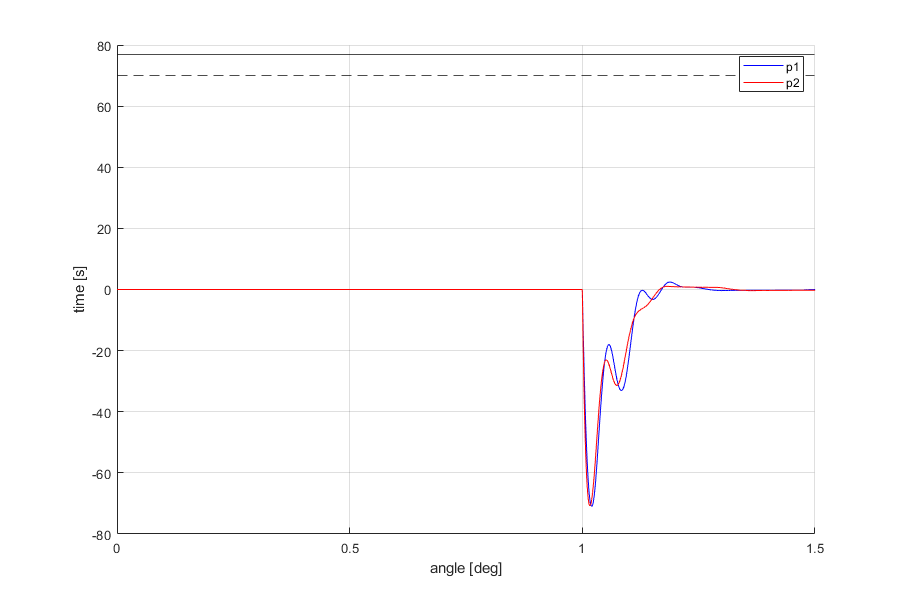

figure('Renderer', 'painters', 'Position', [10 10 900 600])
hold on;
plot(data.test1,data.thlest1,'b');
plot(data.test2,data.thlest2,'r');
% plot(data.test3,data.thlest3,'g');
% plot(data.test4,data.thlest4,'m');
yline(step_size*1.1,'k')
yline(step_size,'k--')
hold off;
legend('p1','p2');%,'p3','p4');
xlabel('angle [deg]');
ylabel('time [s]');
grid on
xlim([0,1.5]);


step_est1 = stepinfo(data.thlest1,data.test1,"SettlingTimeThreshold",0.05)

step_est1 = struct with fields:
        RiseTime: 4.0752e-04
    SettlingTime: 1.1182
     SettlingMin: -0.3477
     SettlingMax: 2.4324
       Overshoot: 1.9543e+03
      Undershoot: 5.9951e+04
            Peak: 70.9860
        PeakTime: 1.0200


step_est2 = stepinfo(data.thlest2,data.test2,"SettlingTimeThreshold",0.05)

step_est2 = struct with fields:
        RiseTime: 7.6981e-06
    SettlingTime: 1.1473
     SettlingMin: -70.7336
     SettlingMax: 1.0424
       Overshoot: 6.5629e+04
      Undershoot: 968.6826
            Peak: 70.7336
        PeakTime: 1.0160
